clc;
clear all;
close all;
pause('off');
s = tf('s');

# **Applied Linear Controls**

# **Final Project**

# **Japnit Sethi**

**Objective:** To design an output feedback control system that can regulate the responses of a multi-input multi-output dynamic system. The Midterm Project will focus on developing and validating an empirical discrete-time state-space model of the dynamic system using system identification methods from the course notes. The Final Project will focus on developing and validating an output feedback controller.  

**Note**: The first step for developing a state feedback or an output feedback controller is to develop a state-space model of the open loop plant, which you completed in the Midterm Project. You must use your own estimated state-space model from the Midterm Project; however, you must correct any problems with your estimated model before attempting the final project!

## Section 1

Before you can use the discrete state-space model from the Midterm Project for a state-feedback control design, you must validate it in the time domain. First generate a pulse excitation signal with a magnitude of 10V. Apply the same pulse excitation to both the model and the s20_plant function to generate simulated and actual responses. Generate a properly annotated figure with two subplots. The first subplot should contain y1 for the simulated and actual responses, and the second subplot should contain y2 for the simulated and actual responses. 

**Note**: The actual responses will have noise on them, but your simulated responses will not!

% REMOVE BINS Etc.
f_s = 2000;             % Sample Rate, Hz (given)
T_s = 1/f_s;            % Sample Time Period, s
% Our sample rate is 2000 samples/sec, and we can only have 0.2 sec of data
% N = 2000*0.2 = 400 data points
N = f_s*0.2;

% Pulse Excitation
u1 = zeros(1, N);
u1(1) = 10;

% Time
t = T_s*(1:length(u1));


%-----------------------------------------------------------
%%%%%%%%%%%% Actual Response (s20_plant()) %%%%%%%%%%%%%%%%
%-----------------------------------------------------------

% Applying Pulse excitation to s20_plant()
y_actual = s20_plant(u1); % MAKE SURE THAT THE SATURATION DOES NOT GO ABOVE 0.1%
y1_actual = y_actual(1,:);         
y2_actual = y_actual(2,:);   

%----------------------------------------------------
%%%%%%%%%%%% Simulated Response (Model) %%%%%%%%%%%%%%%%
%----------------------------------------------------

% Import the open-loop system from the file "Midterm_OL_SS_LTI_Model.mat":
load('Midterm_OL_SS_LTI_Model.mat');  
ss_open = H_ss_reduced;
[y_simulated, t, x_simulated] = lsim(ss_open, u1, t);

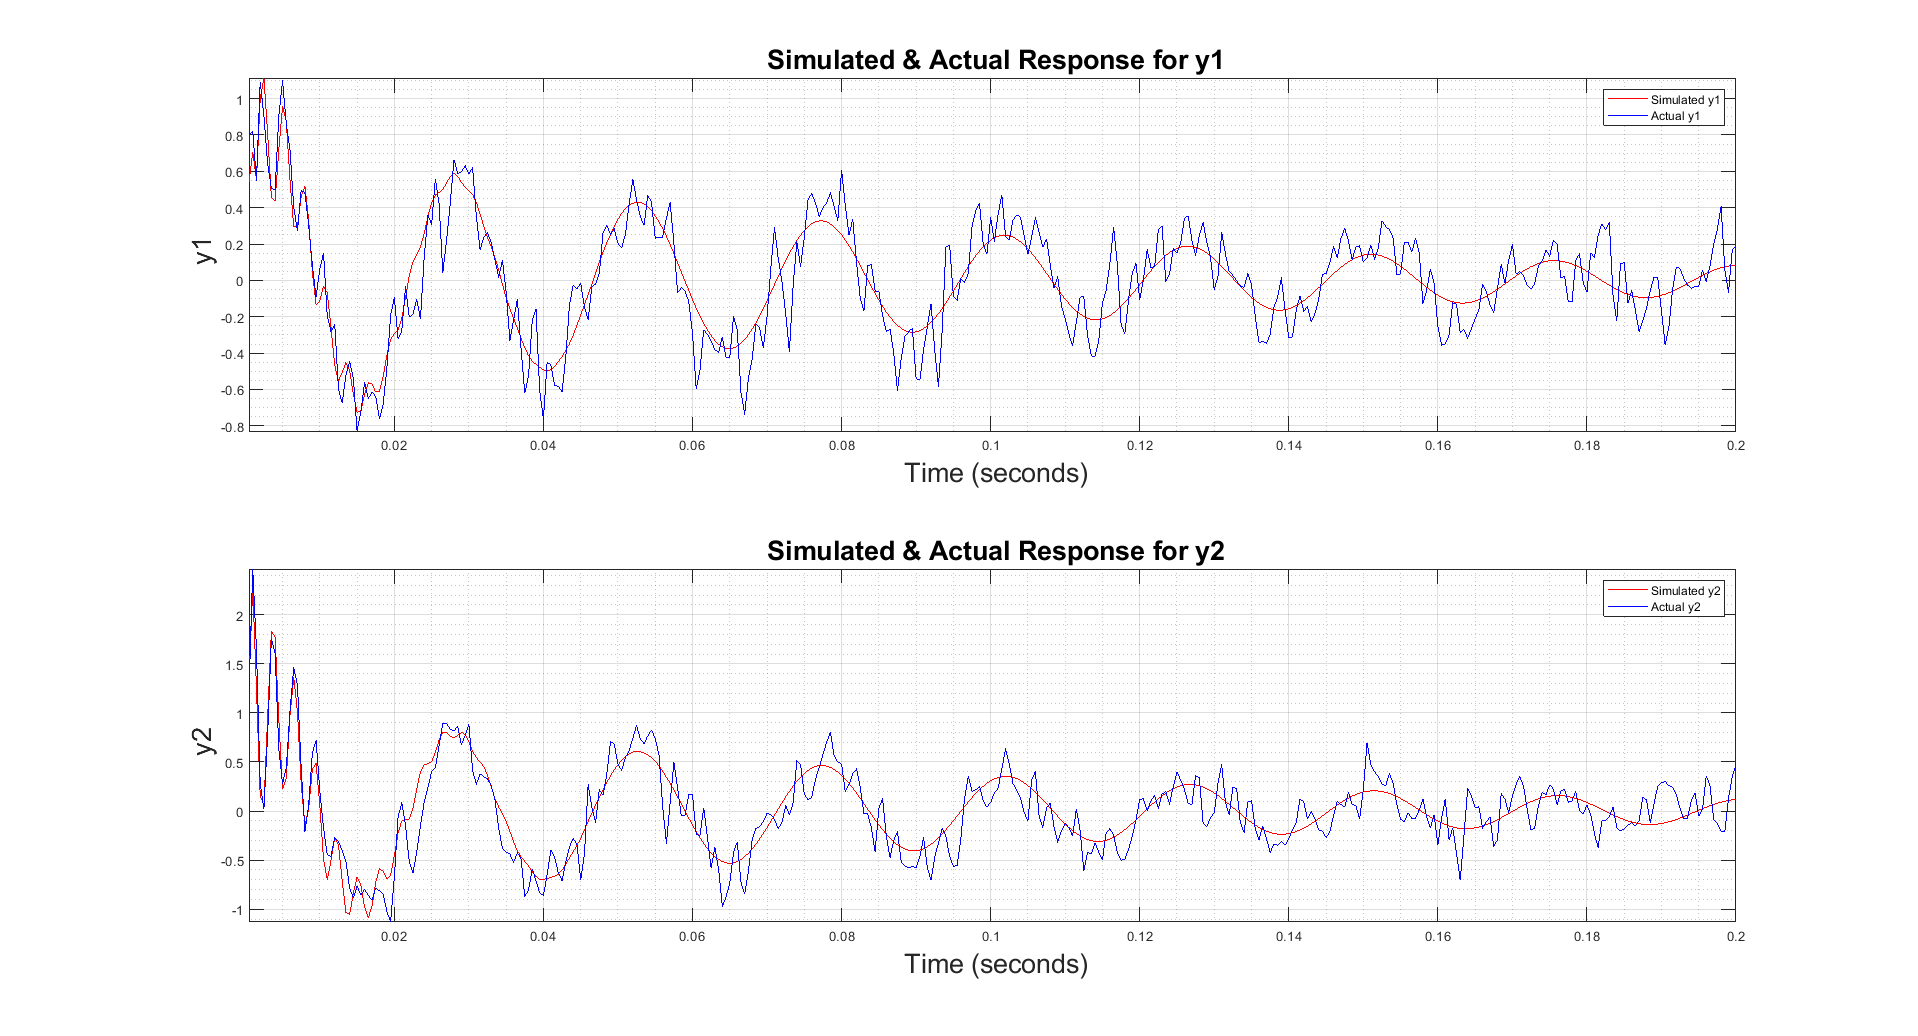

y1_simulated = y_simulated(:,1);         
y2_simulated = y_simulated(:,2);  
      

% Plots
figure()
subplot(2, 1, 1)
plot(t, y1_simulated, 'r');
hold on
grid on
grid minor
axis tight
plot(t, y1_actual,'b'); 
% yline(10,'--','Max limit for u','LineWidth',2);
% yline(-10,'--','Min limit for u','LineWidth',2);
% xlim([0, max(t)]); 
% ylim([-12 12]);
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} y1', 'interpreter', 'tex'); 
title('\fontsize{20} Simulated & Actual Response for y1', 'interpreter', 'tex');
legend('Simulated y1', 'Actual y1');
hold off

subplot(2, 1, 2)
plot(t, y2_simulated, 'r');
hold on
grid on
grid minor
axis tight
plot(t, y2_actual,'b'); 
% xline(nyquist,'--','Nyquist','LineWidth',2);
% xlim([Frequency_min_new, nyquist]); 
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} y2', 'interpreter', 'tex'); 
title('\fontsize{20} Simulated & Actual Response for y2', 'interpreter', 'tex');
legend('Simulated y2', 'Actual y2');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## **Section 2**

Before you can develop either a state feedback controller or an outputfeedback controller, you must next test for controllability and observability. Use your discrete state-space model from the Midterm Project to demonstrate that the open-loop system is completely controllable and completely observable.

### **Controllability**

If the rank of the controllability matrix is equal to the maximum possible rank, then the system is **controllable**.

**For example**: If we have a controllability matrix K, that has a rank N, where N is the number of columns of A matrix of size NxN, and matrix K is defined as $K=\left\lbrack B,\textrm{AB},A^2 B,A^3 B,\ldotp \ldotp \ldotp \ldotp A^{N-1} B\right\rbrack$

In our Case, N = 7, and thus K martrix is full rank iff rank(K) = 7

**Note**: We only have 1 Input

### **Observability**

The** reason** we need to check for observability is because just like controller design problem we check for controllability, we need to check if the observability matrix is full rank such that we can arbitarily place poles of an observer we design.

If the rank of the observability matrix is equal to the maximum possible rank, then the system is **observable**.

**For example**: If we have aobservability matrix O, that has a rank N, where N is the number of columns of A matrix of size NxN, and matrix O is defined as $O=\left\lbrack C^{\prime } ,{A^{\prime } C}^{\prime } ,{A^{\prime } }^2 C^{\prime } ,{A^{\prime } }^3 C^{\prime } ,\ldotp \ldotp \ldotp \ldotp {A^{\prime } }^{N-1} C^{\prime } \right\rbrack$

In our Case, N = 7, and thus O martrix is full rank iff rank(O) = 7

% Extract the open-loop A, B, C, and D matrices from the OL system
A_OL = ss_open.a;
B_OL = ss_open.b;
C_OL = ss_open.c;
D_OL = ss_open.d;

%------------------------------------------
%%%%%%%%%%%% Controllability %%%%%%%%%%%%%%
%------------------------------------------

K_Controllability = ctrb(ss_open);
Rank_K_Controllability = rank(K_Controllability); % rank(A_OL, B_OL);

fprintf(' The rank of the controllability matrix is: %d', Rank_K_Controllability);

 The rank of the controllability matrix is: 7


if Rank_K_Controllability == 7
    disp(' Thus, the LTI system is completely controllable ');
end

 Thus, the LTI system is completely controllable 




%------------------------------------------
%%%%%%%%%%%% Observability %%%%%%%%%%%%%%%%
%------------------------------------------

O_Observability = obsv(ss_open); % Observability matrix with no outputs zero'd
Rank_O_Observability = rank(O_Observability); % rank(A_OL, C_OL);

fprintf(' The rank of the observability matrix is: %d ', Rank_O_Observability);

 The rank of the observability matrix is: 7 

if Rank_O_Observability == 7
    disp(' Thus, the LTI system is completely observable ');
end

 Thus, the LTI system is completely observable 


% Do not need to check for subsets here

## **Section 3**

Use the Matlab** lqr()** function to design a full state feedback gain matrix for the discrete-time open-loop system. You must design positive definite Q and R weighting matrices to meet the following design requirements:

### **LQR(Linear-Quadratic Regulator) Design**

The LQR function requires a state weighing matrix **Q** and an actuator weighing matrix **R**.

State weighing matrix **Q**:

In order to design the State weighing matrix Q, we will use the "output weighing"

Let $\overset{\cdot }{Q}$ be the output weighing matrix, the we can calculate Q as:

Q = $C_{\textrm{OL}}^T *\overset{\cdot }{Q} *C_{\textrm{OL}} \;$, where $C_{\textrm{OL}} \;$ is the C matrix of the Open-loop system and $C_{\textrm{OL}}^T$ is it's transpose

**Note**: Varying the weighting matrices **Q** and **R** allows us to trade off the "size" of the state response with the size of the control effort. For example,

If $\left|Q\right|$ <<$\left|R\right|$, then cost function will minimize the amount of control effort needed (i.e. gains will be small).

If $\left|Q\right|$ >>$\left|R\right|$, then cost function will minimize the state response without regard to amount of control effort needed (i.e. gains will be large).

**Note**: Q is technically going to be a diagonal matrix, with each diagonal element corresponding to a specific state, so for example we want state element 1 to have the least error then we can make the diagonal element from the Q  matrix corresponding to state element 1 larger than others to do so.

R is similar to Q but acts on the input vector.

**Simulation Test Conditions:**

- Choose zero initial conditions for the model at t=0; however, you are not allowed to reset the state initial conditions back to zero for any time after t=0

- Hold the excitation constant at **u=4** for the** first 10 ms** of the simulation. Note that this first interval of time is required to demonstrate the open-loop response to a constant excitation

- At time t = 10 ms, apply your LQR full state feedback control law to the model, assuming you have complete knowledge of the state vector. Do NOT use a state estimator! You can NOT use any Matlab simulation functions such as lsim.

- Terminate your simulation at t = 30ms

**Mandatory Performance Requirements:**

- The **control signal** must always be bounded within the **saturation limits of ±10V**

- All **responses** must always be bounded** within the saturation limits of ±10V**

- All** responses **must be **settled to within ±0.5V after t = 20 ms.**

% initial conds of all S-states & derivatives
x_0 = zeros(7,1);   % State 0


% Let's assume our Q_star (output weighing matrix) to be:
% 2 Outputs
Q_star = 10* [1, 0;...
                0, 1];
  
% Therefore, Our Q (State wighing matrix) is:
Q = C_OL' * Q_star * C_OL;
R = diag(2);                      % 1 Input
[K_lqr,S_lqr,P_lqr] = lqr(ss_open,Q,R);
% where K is my state feedback gain matrix, S is the Riccati solution and P
% are the closed loop eigen values

## **Section 4**

Simulate the closed-loop system response of your model with the LQR state feedback control law assuming that you have complete knowledge of the discrete time state vector. Plot the closed-loop time responses up to 30 ms using the Matlab **stairs** function (read the help file). Your single figure must contain two properly formatted and annotated subplots. The upper subplot will include both outputs and the lower subplot will include the control signal. Use a legend to identify specific signals. You must plot horizontal dashed lines at ±0.5V from 20ms to 30ms to demonstrate that your design meets the convergence requirement.

You will next need to develop an output feedback controller and evaluate its performance on the actual system. To do this, you will need to use s20_plant.p with a different call structure. The new call structure is given by: 

[ y, u, xhat ] = s20_plant( dt_ofc, time );

where y is a 2XN matrix of output sensor responses from the actual system, u is a 1XN matrix of the output control signals, and xhat is a NSXN matrix of estimated state responses, where N is the total number of samples of data collected, and NS is the number of states in your open-loop discrete-time model. As in any real physical system, you do not have access to the actual state vector. Using these outputs, you will need to reconstruct the observer output yhat for generating the validation comparison plots  

**Note**: you do NOT define the control signal as an input!

The input variable **dt_ofc** is a discrete-time state-space LTI object that you must generate to represent the complete output feedback controller. This controller must implement the following discrete-time state and output equations:


$$\hat{x_{k+1} } =A_{\textrm{ofc}} \cdot \hat{x_k } \;+B_{\textrm{ofc}} \cdot \left\lbrack \begin{array}{c}
u_k \\
y_k 
\end{array}\right\rbrack$$
                
$$u_k =C_{\textrm{ofc}} \cdot \hat{x_k } \;+0\cdot \left\lbrack \begin{array}{c}
u_k \\
y_k 
\end{array}\right\rbrack$$


This is the only structure that s20_plant will accept so you will need to determine the appropriate A, B, and C matrices for this state-space object (D is required to be the zero matrix as shown above). The second input argument, time, allows you to define the total duration of the data set as well as the start time for control.

**Note** that you will NOT specify the number of samples N directly! The observer will always begin at t=0, and the observer will always start with zero initial conditions. The dynamic plant inside s20_plant.p will have a random (unknown) initial condition every time you call the function, to emulate a real-world situation.

To specify both the final time (seconds) and a controller start time (seconds), select:

tstart = 10e-3;  % 10ms

tfinal = 30e-3;  % 30 ms

time = [tstart, tfinal];

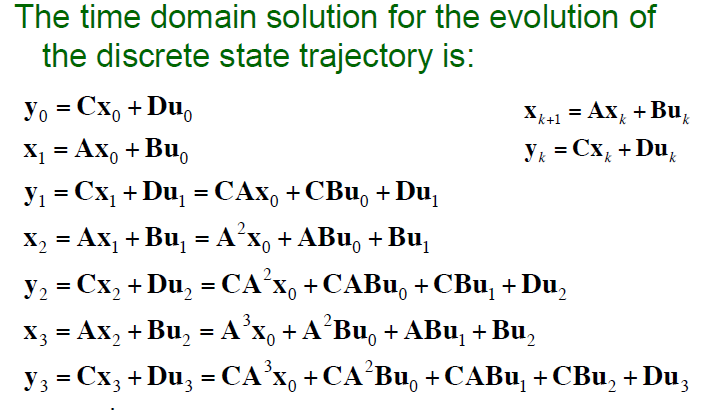

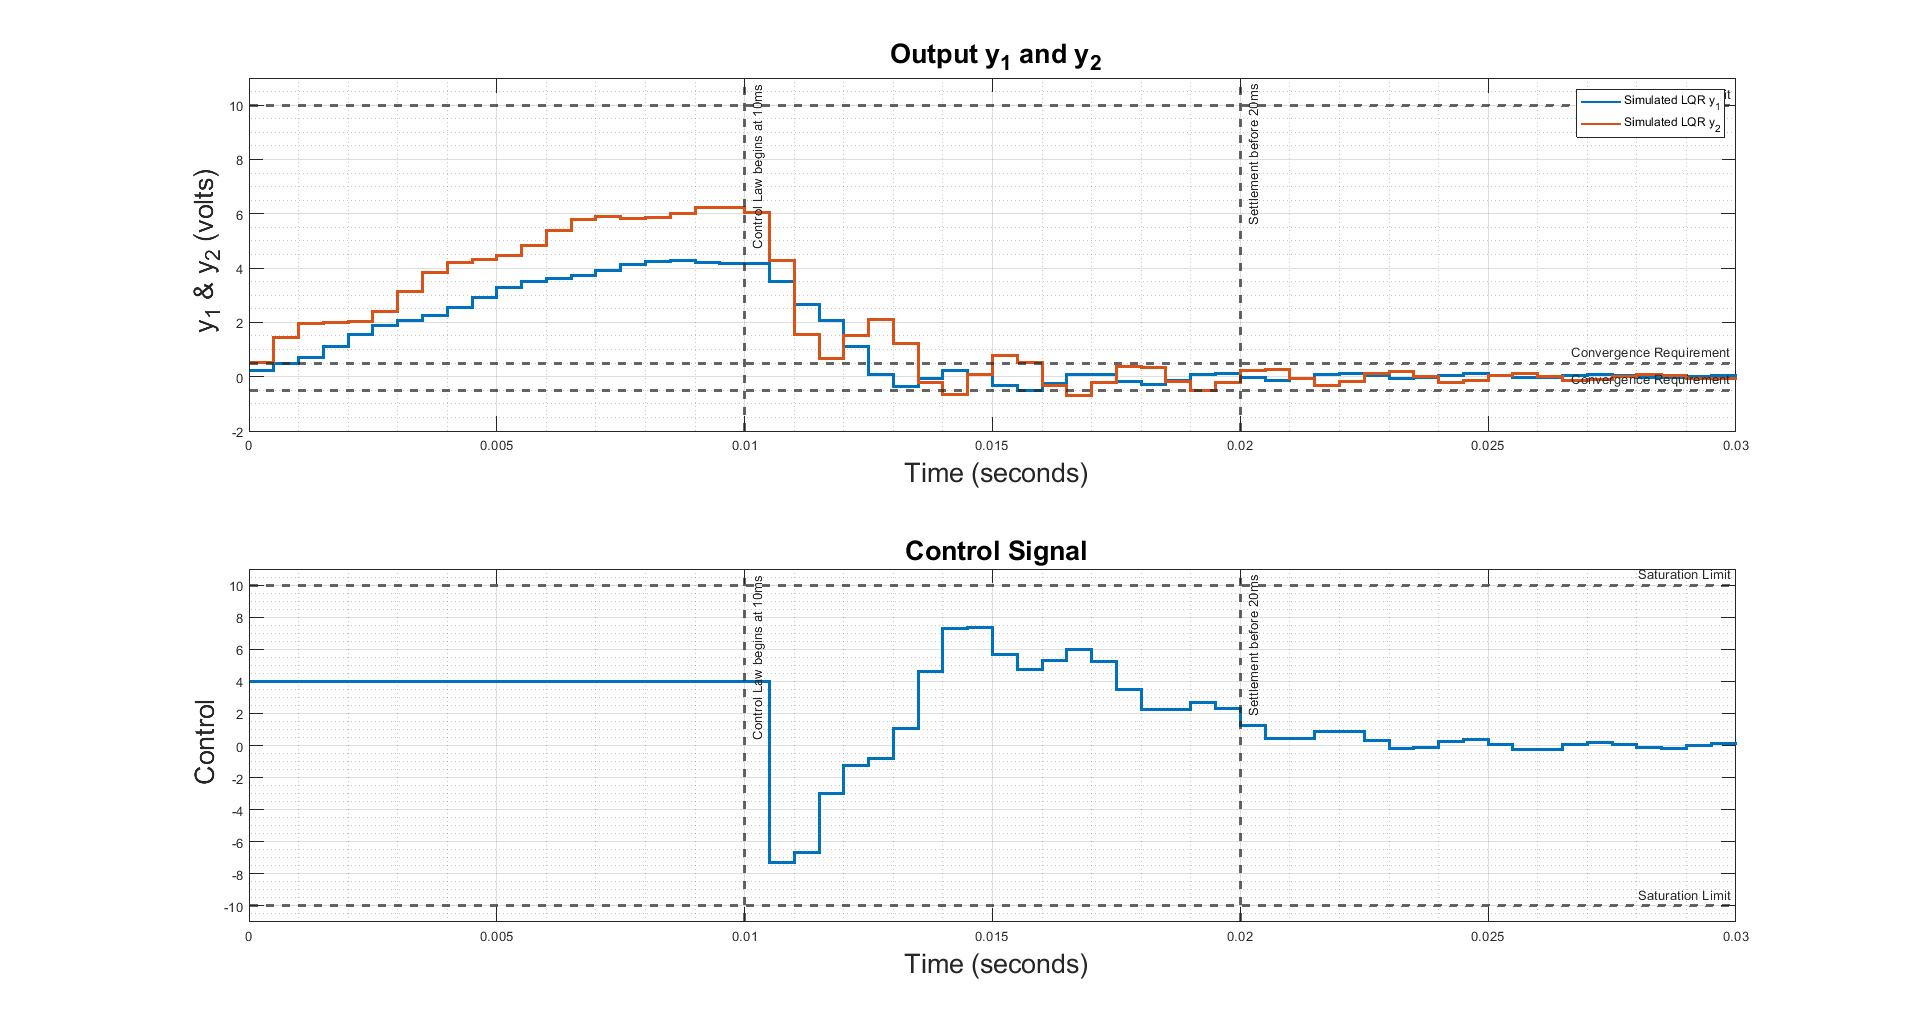

tstart = 10e-3;     % 10 ms
tfinal = 30e-3;     % 30 ms
time = [tstart, tfinal];

%------------------------------------------------------------------
%%%%%%%%%%%% Full state Feedback using LQR control %%%%%%%%%%%%%%%%
%------------------------------------------------------------------
% Our sample rate is 2000 samples/sec, for 30e-3 seconds of data
N_samples = 30e-3*2000; % Total number of samples
% No of samples for First 10 ms (10ms = 0.01s)
N_nocontrol = N_samples/3;

%Similarly for second half that includes application controller from 10 ms
%to 30ms (so total 20 ms of control), we have:
%data points
N_control = 2*N_samples/3;

% Constant excitation of 4
u_nocontrol = 4;
u_lqr = u_nocontrol*ones(1, 21);

x_lqr = x_0;

for i = 1:N_samples+1
    if i <= N_nocontrol
        x_lqr(:, i+1) = A_OL*x_lqr(:, i) + B_OL*u_nocontrol;
        y_lqr(:, i) = C_OL*x_lqr(:,i) + D_OL*u_nocontrol;        
    elseif i == N_nocontrol+1
        y_lqr(:, i) = C_OL*x_lqr(:,i) + D_OL*u_nocontrol;
        x_lqr(:, i+1) = A_OL*x_lqr(:,i) + B_OL*u_lqr(:, i);
    elseif i > (N_nocontrol+1) && i <= N_samples
        u_lqr(:, i) = -K_lqr*x_lqr(:, i-1);
        x_lqr(:, i+1) = A_OL*x_lqr(:,i) + B_OL*u_lqr(:, i);  
        y_lqr(:, i) = C_OL*x_lqr(:,i) + D_OL*u_lqr(:, i);
    elseif i == (N_samples+1)
        u_lqr(:, i) = -K_lqr*x_lqr(:, i-1);
        y_lqr(:, i) = C_OL*x_lqr(:,i) + D_OL*u_lqr(:, i); 
    end
end

% Time, +1 for the 0th response
t_lqr = linspace(0, tfinal, N_samples+1);


%----------------------------------
%%%%%%%%%%%% Plotting %%%%%%%%%%%%%
%----------------------------------
figure()
subplot(2, 1, 1)
stairs(t_lqr,y_lqr(1,:),'LineWidth',2);
hold on
grid on
grid minor
stairs(t_lqr,y_lqr(2,:),'LineWidth',2);
yline(0.5,'--','Convergence Requirement','LineWidth',2);
yline(-0.5,'--','Convergence Requirement','LineWidth',2);
yline(10,'--','Saturation Limit','LineWidth',2);
% yline(-10,'--','Saturation Limit','LineWidth',2);
xline(0.01,'--','Control Law begins at 10ms','LineWidth',2);
xline(0.02,'--','Settlement before 20ms','LineWidth', 2);
% xlim([0, max(t)]); 
ylim([-2 11]);
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} y_1 & y_2 (volts)', 'interpreter', 'tex'); 
title('\fontsize{20} Output y_1 and y_2', 'interpreter', 'tex');
legend('Simulated LQR y_1', 'Simulated LQR y_2');
hold off

subplot(2, 1, 2)
stairs(t_lqr, u_lqr,'LineWidth',2);
hold on
grid on
grid minor
xline(0.01,'--','Control Law begins at 10ms','LineWidth',2);
xline(0.02,'--','Settlement before 20ms','LineWidth', 2);
yline(10,'--','Saturation Limit','LineWidth',2);
yline(-10,'--','Saturation Limit','LineWidth',2);
ylim([-11 11]);
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Control', 'interpreter', 'tex'); 
title('\fontsize{20} Control Signal', 'interpreter', 'tex');
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% Checking if the y_1 and y_2 are within +0.5 and -0.5 V, from 20ms to 30ms
T_greaterthan20 = find(t_lqr >= 0.02); % Vector of Index positions for time between 20ms to 30ms

% Y_1 and Y_2 indices where it is out of the convergence criteria of > 0.5 and
% < -0.5 from 20ms to 30ms
y_1check = find(abs(y_lqr(1, T_greaterthan20:length(y_lqr))) > 0.5);
y_2check = find(abs(y_lqr(2, T_greaterthan20:length(y_lqr))) > 0.5);
if isempty(y_1check & y_2check)
    disp('Y_1 and Y_2 meet convergence criteria of within +-5 V');
end

Y_1 and Y_2 meet convergence criteria of within +-5 V


## **Section 5**

For any practical implementation of full-state feedback control, you must estimate the state vector. Design the Kalman state feedback gains using the following Matlab function call:

[LTI, K] = kalman(my_ss_model, QN, RN, NN, 'current')

where: QN is a 2x2 process noise covariance matrix, RN is a 2x2 measurement noise covariance matrix, and NN is a 2x2 cross covariance matrix between the process noise and sensor noise. You can estimate the measurement noise covariance matrix using the **COV function** in Matlab (read the help to learn how). The cross covariance noise matrix NN can be assumed to be zero. As is common in practice, the process noise covariance matrix is the most difficult to determine. It certainly cannot be chosen to be zero, but it should be positive definite. You may choose QN = alpha*eye(2) where alpha is a “tuning” gain that you must select by trial and error. The KALMAN function outputs an LTI object sys as well as the Kalman feedback gains K. You will only use the **Kalman feedback gain K**! (Display your final Kalman feedback gains to the Matlab command window)

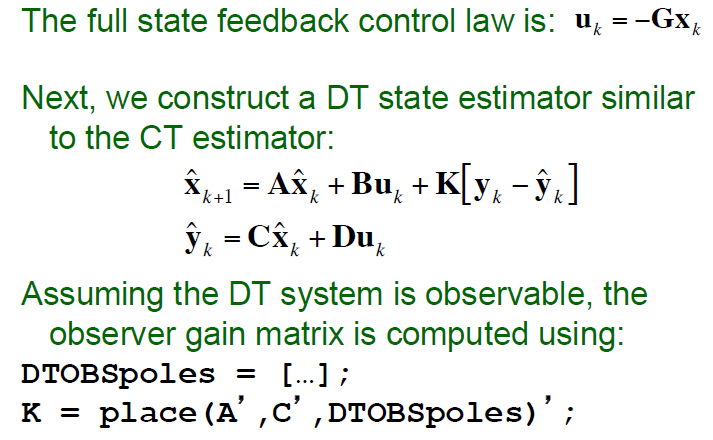                 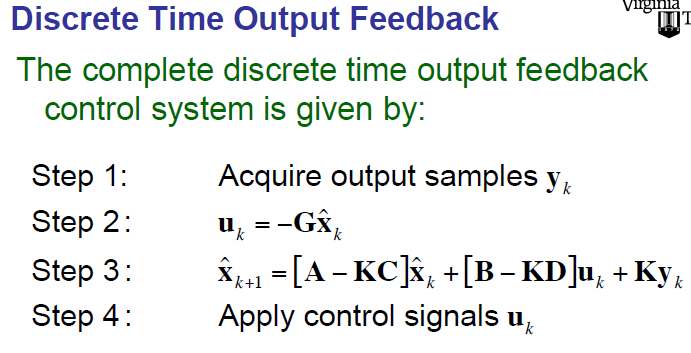

% %------------------------------------------------------------------------
% %%%%%%%%%%%% Kalman Filter to estimate state Feedback gains %%%%%%%%%%%%%
% %------------------------------------------------------------------------

% Calculating Magnitude of noise without any input i.e. turning off input u
No_Input = 0*u_lqr;             
y_No_input = s20_plant(No_Input);   
n1 = y_No_input(1,:);
n2 = y_No_input(2,:);

alpha = 8;                       % Tuning gain
QN = alpha;                      % process noise covariance
RN = cov(n1, n2);                % measurement noise covariance
NN = zeros(1,2);                   % cross covariance;
[~, K_kalman] = kalman(ss_open, QN, RN, NN, 'current')

K_kalman =     1.6874    1.3366
   -0.4967   -0.4291
   -1.3249   -1.3956
   -0.1163    0.5392
    0.1899    0.1291
    0.1575    0.1130
   -0.7555   -0.5225


A_dtofc = A_OL- K_kalman*C_OL; 
B_dtofc = [B_OL - K_kalman*D_OL K_kalman];
C_dtofc = -K_lqr;
D_dtofc = [];


## **Section 6**

Construct the discrete-time state-space output feedback controller LTI object as defined above, then generate the closed-loop response of your output feedback controller by inputting the dt_ofc object to the s20_plant.p file with the specified time limits. Plot the closed-loop time responses up to 30 ms using the Matlab stairs function. Your single figure must contain three properly formatted and annotated subplots. The upper subplot will include the actual y1 output, the estimated y1 output, and the error between the actual and estimated y1 outputs. The middle subplot will include the actual y2 output, the estimated y2 output, and the error between the actual and estimated y2 outputs. The lower subplot will include the control signal. Your solution must meet the mandatory performance requirements defined in Section 4. This may require you to run the simulation multiple times.

%------------------------------------------------------------------
%%%%%%%%%%%% Discrete time Output Feedback Controller %%%%%%%%%%%%%
%------------------------------------------------------------------
dt_ofc = ss(A_dtofc, B_dtofc, C_dtofc, D_dtofc);
[y_final, u_final, xhat] = s20_plant(dt_ofc, time);


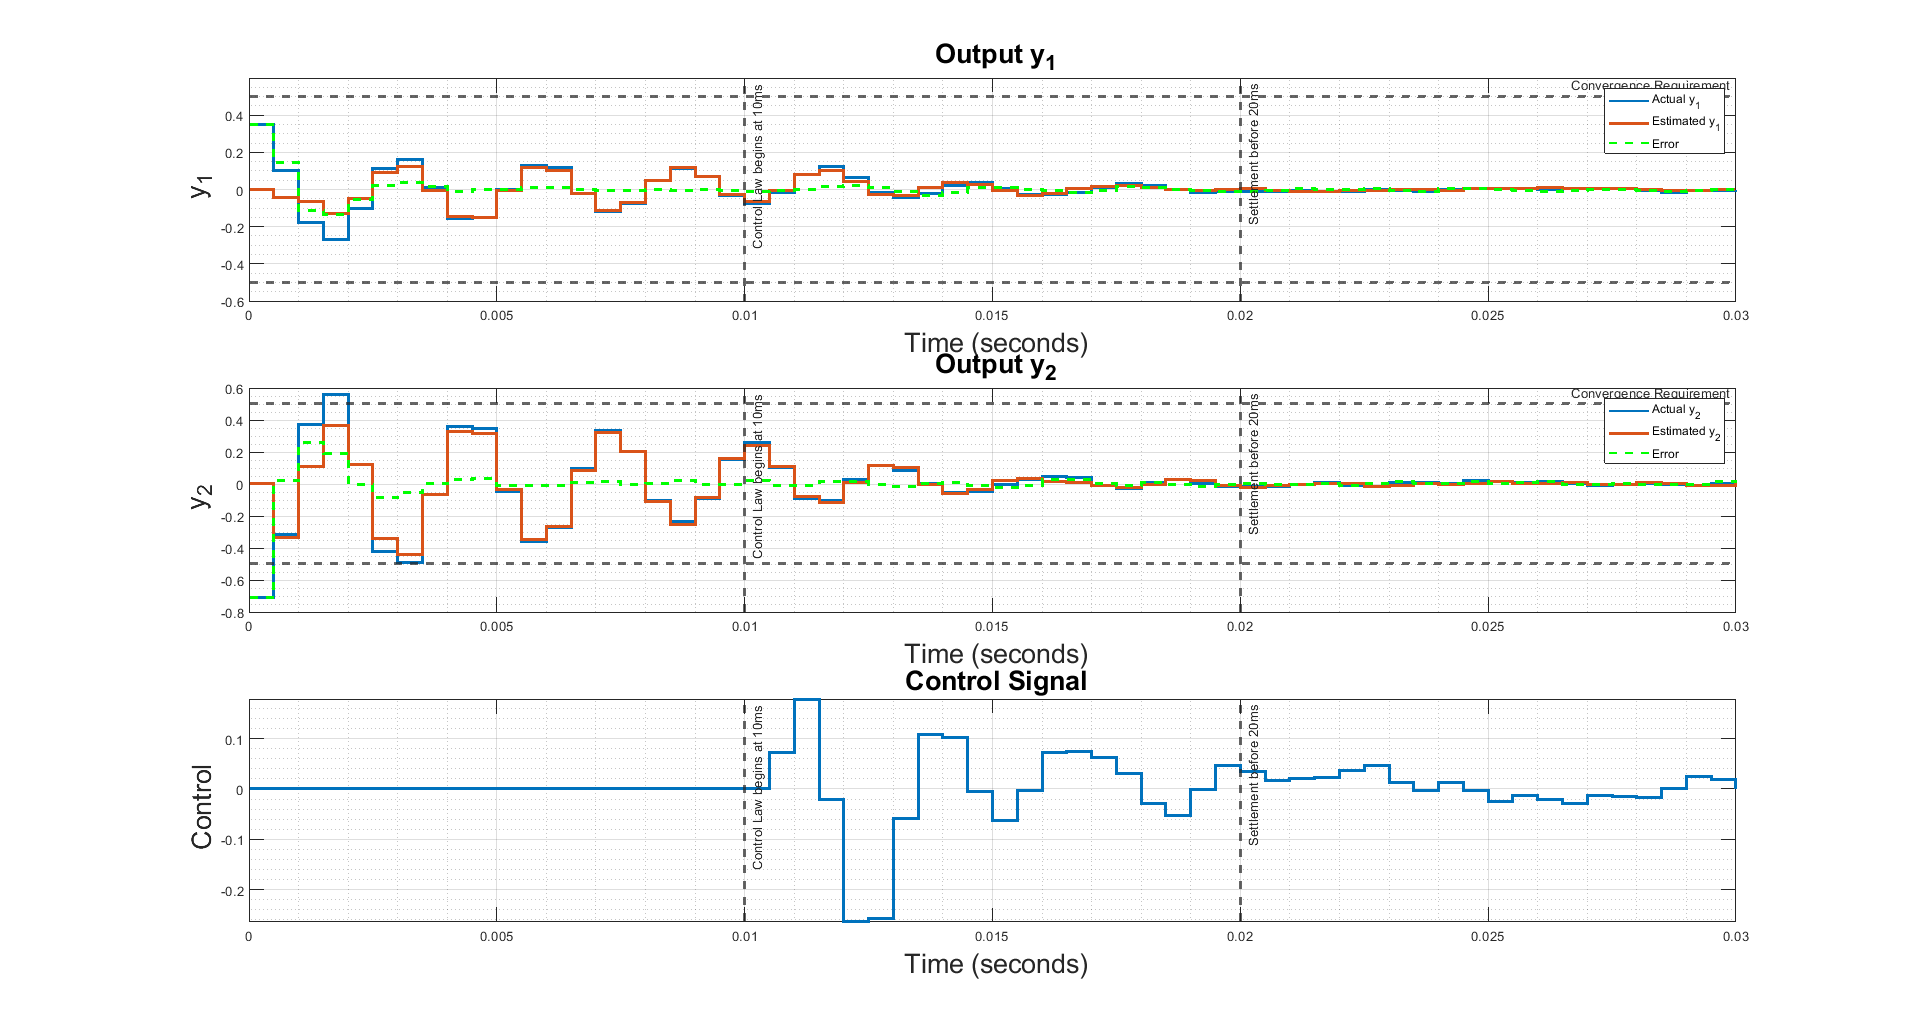


% Compute Estimated Response
yhat = C_OL*xhat +D_OL*u_final;

% Compute Error
e1 = y_final(1, :) - yhat(1, :);
e2 = y_final(2, :) - yhat(2, :);

%----------------------------------
%%%%%%%%%%%% Plotting %%%%%%%%%%%%%
%----------------------------------
figure()
subplot(3, 1, 1)
stairs(t_lqr,y_final(1,:),'LineWidth',2);
hold on
grid on
grid minor
% axis tight
stairs(t_lqr, yhat(1,:),'LineWidth',2);
stairs(t_lqr, e1, 'g', 'LineStyle', '--', 'LineWidth',2);
yline(0.5,'--','Convergence Requirement','LineWidth',2);
yline(-0.5,'--','LineWidth',2);
xline(0.01,'--','Control Law begins at 10ms','LineWidth',2);
xline(0.02,'--','Settlement before 20ms','LineWidth', 2);
% xlim([0, max(t)]); 
ylim([-0.6 0.6]);
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} y_1', 'interpreter', 'tex'); 
title('\fontsize{20} Output y_1', 'interpreter', 'tex');
legend('Actual y_1', 'Estimated y_1', 'Error');
hold off

subplot(3, 1, 2)
stairs(t_lqr,y_final(2,:),'LineWidth',2);
hold on
grid on
grid minor
% axis tight
stairs(t_lqr, yhat(2,:),'LineWidth',2);
stairs(t_lqr, e2, 'g', 'LineStyle', '--', 'LineWidth',2);
yline(0.5,'--','Convergence Requirement','LineWidth',2);
yline(-0.5,'--','LineWidth',2);
xline(0.01,'--','Control Law begins at 10ms','LineWidth',2);
xline(0.02,'--','Settlement before 20ms','LineWidth', 2);
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} y_2', 'interpreter', 'tex'); 
title('\fontsize{20} Output y_2', 'interpreter', 'tex');
legend('Actual y_2', 'Estimated y_2', 'Error');

subplot(3, 1, 3)
stairs(t_lqr, u_final,'LineWidth',2);
hold on
grid on
grid minor
axis tight
xline(0.01,'--','Control Law begins at 10ms','LineWidth',2);
xline(0.02,'--','Settlement before 20ms','LineWidth', 2);
% xlim([Frequency_min_new, nyquist]); 
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Control', 'interpreter', 'tex'); 
title('\fontsize{20} Control Signal', 'interpreter', 'tex');
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

% Checking if the e1 and e2 are nearly 0 between 10ms to 30ms
T_greaterthan10 = find(t_lqr >= 0.01); % Vector of Index positions for time between 10ms to 30ms

% Max Absolute Error value between 10ms and 30ms
max(abs(e1(1, T_greaterthan10:length(e1))))

ans = 0.0309

max(abs(e2(1, T_greaterthan10:length(e2))))

ans = 0.0304


% e1 and e2 indices where it is >0.05 or < -0.05
e1check = find(abs(e1(1, T_greaterthan10:length(y_lqr))) > 0.05);
e2check = find(abs(e2(1, T_greaterthan10:length(y_lqr))) > 0.05);
if isempty(e1check)
    disp('e1 is within +-0.05 after 10ms');
else
    disp('e1 is not within +-0.05 after 10ms')
end

e1 is within +-0.05 after 10ms


if isempty(e2check)
    disp('e2 is within +-0.05 after 10ms');
else
    disp('e2 is not within +-0.05 after 10ms')
end

e2 is within +-0.05 after 10ms
